### This exercise uses spectral analysis of microtopography on an exposed fault surface to determine the dominent dimension of topographic roughness, indicating the stronger directional component of fault slip.

We'll start by clearing our working memory and figures (good practice for any Matlab script), and then loading our fault microtopography sample data.

clear
clf

load('FaultSample.mat');

 "FaultSample" should now show up as a variable in your workspace. Notice that it's a data structure (1x1 struct)--you can look up the documentation for data structures to learn more about their useage. Try double clicking on the variable to bring up its contents in the Variable window, or use the command window to read out its contents:

%Report contents of data structure
FaultSample

FaultSample = struct with fields:
        Z: [64×512 double]
       dx: 0.0040
     name: 'Venere_small2_fp1.2.xyz'
    units: 'meters'


The data structure should contain **Z** (elevation at each point on 64x512 xy grid),** dx** (the distance between each spatial sample in Z), **units** (in which Z and dx are reported, should be meters), and **name** of the sample (useful for tracking multiple datasets).

Now we'll create **x** and **y** vectors to describe the cell positions of our elevation grid. We'll also extract the elevation array **z** from the data structure for easier accress.

%make x & y vectors in real units (meters)
dx = FaultSample.dx; %take dx from FaultSample structure
x = dx/2:dx:512*dx-dx/2; %center x and y vectors in bins
y = dx/2:dx:64*dx-dx/2;
z = FaultSample.Z; %take elevation z from structure

Use the Workspace window or whos command to query more information about these vectors so you understand what we've done here:

whos X Y Z

Note which variable (**x** or **y**) corresponds to rows or columns of **z**.

Now plot the elevation data with real x-y units to visualize your fault topography: 

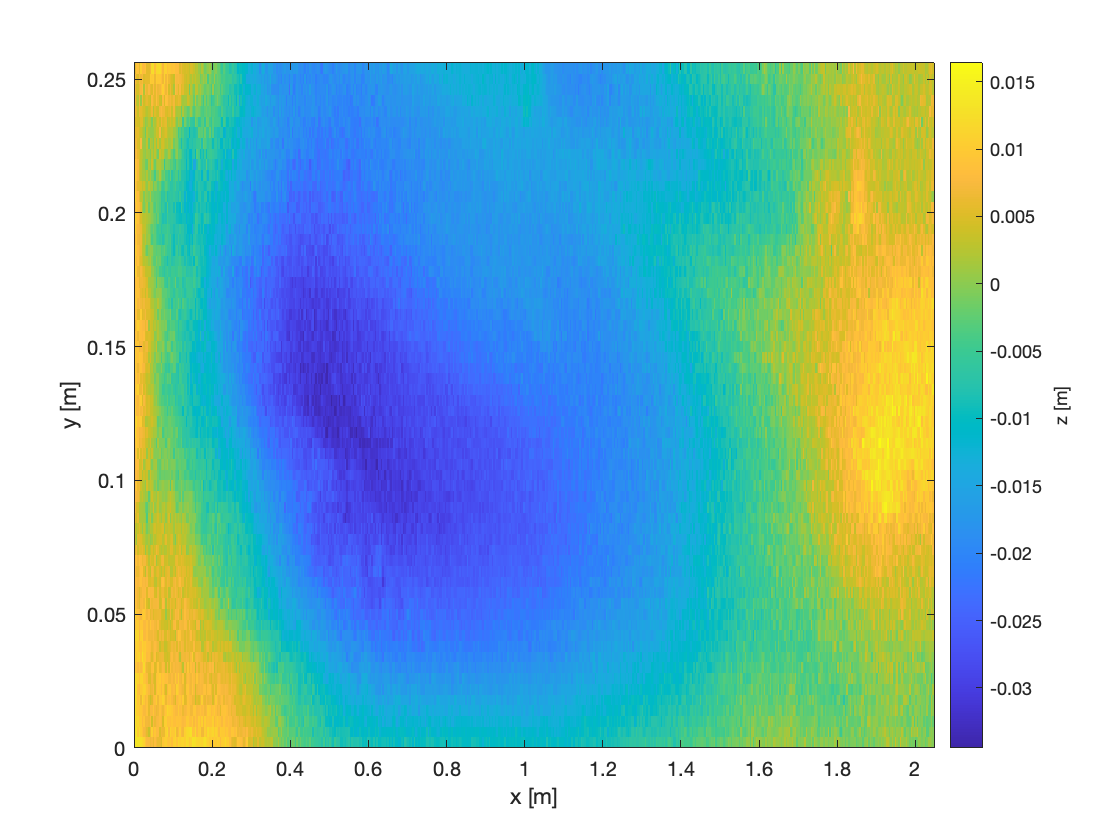

%plot elevation in xy-space
figure(1)
clf
imagesc(x,y,z);

%set origin to lower left corner and label axes
axis xy;
xlabel('x [m]');
ylabel('y [m]');

%add and label a colorbar
c = colorbar;
set(get(c,'label'),'string','z [m]','Rotation',90);

#### *Can you identify the dominant direction of fault slip (i.e., x- or y-direction) from looking at this figure?  *

## Let's try some spectal analysis!

We'll start with just 1D periodograms of a random row and column of z.

Pull out a random row and column of **z** and treat them as 1D sample vectors to make test periodograms:

%Select a random row (yr) and column (xr) of z
yr = randi(length(y));
xr = randi(length(x));
zx=z(yr,:);
zy=z(:,xr);

figure(2)
clf
%Show surface again with lines showing random transect locations
subplot(3,1,1)
imagesc(x,y,z); %same plot as before
axis xy;
xlabel('x [m]');
ylabel('y [m]');
xlim([x(1) x(end)]);
ylim([y(1) y(end)]);
c = colorbar;
set(get(c,'label'),'string','z [m]','Rotation',90);
hold on
plot([x(1) x(end)],[y(yr) y(yr)],[x(xr) x(xr)],[y(1) y(end)]); %plot a line at each transect location
title('Random Transects')

%Plot the topographic cross section of each random transect
subplot(3,1,2)
plot(x,zx,y,zy);
xlabel('horizontal distance [m]')
ylabel('z [m]')
legend('x-direction','y-direction','location','southeast')

Calculate the periodogram for each random transect.

% Identify the spatial sampling frequency
fs = 1/dx; %units of samples/meter
  
%Calculate a 1D periodogram for each of these random samples
windowx = hamming(length(zx)); %create hamming window to taper signal and avoid edge artifacts
nfftx = length(zx); %number of samples to use for DFT
[Pxx,fx] = periodogram(detrend(zx),windowx,nfftx,fs,'psd');

windowy = hamming(length(zy)); 
nffty = length(zy); 
[Pyy,fy] = periodogram(detrend(zy),windowy,nffty,fs,'psd');

*Note that while we selected a random row (y value), this extracts a sample that varies in x (i.e., across multiple columns). Hence Pxx is a periodogram over x, while Pyy is a periodogram over y.*

#### Now plot these periodograms:

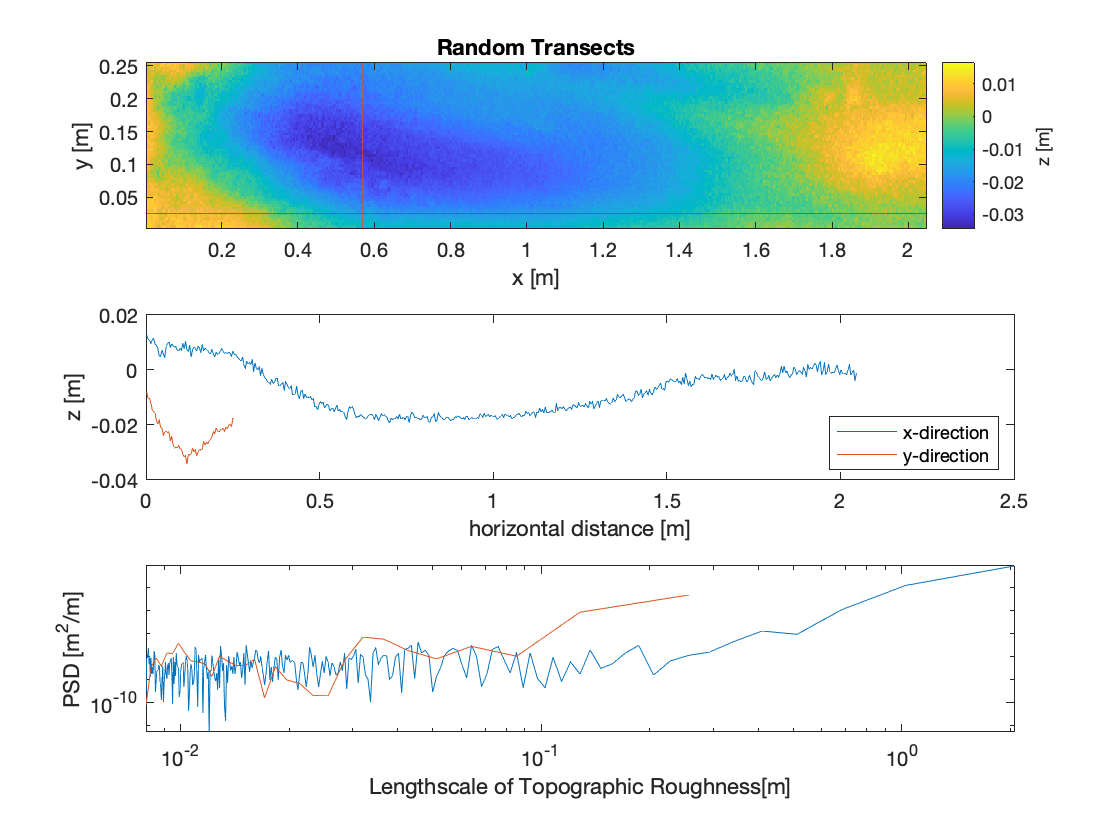

%turn frequency vectors into wavelength (= lengthscale of topographic roughness = 1/freq)
wx=1./fx;
wy=1./fy;

figure(2)
%Plot periodograms on loglog axes using wavelength instead of spatial frequency
subplot(3,1,3)
loglog(wx,Pxx,wy,Pyy)
xlabel('Lengthscale of Topographic Roughness[m]')
ylabel('PSD [m^2/m]')

#### *Try rerunning this section a few times to see what different random transects look like and get a sense of the spatial variation in roughness.*

## Average spectra

We can also make average spectra in the x and y directions to examine the difference in mean directional roughness.

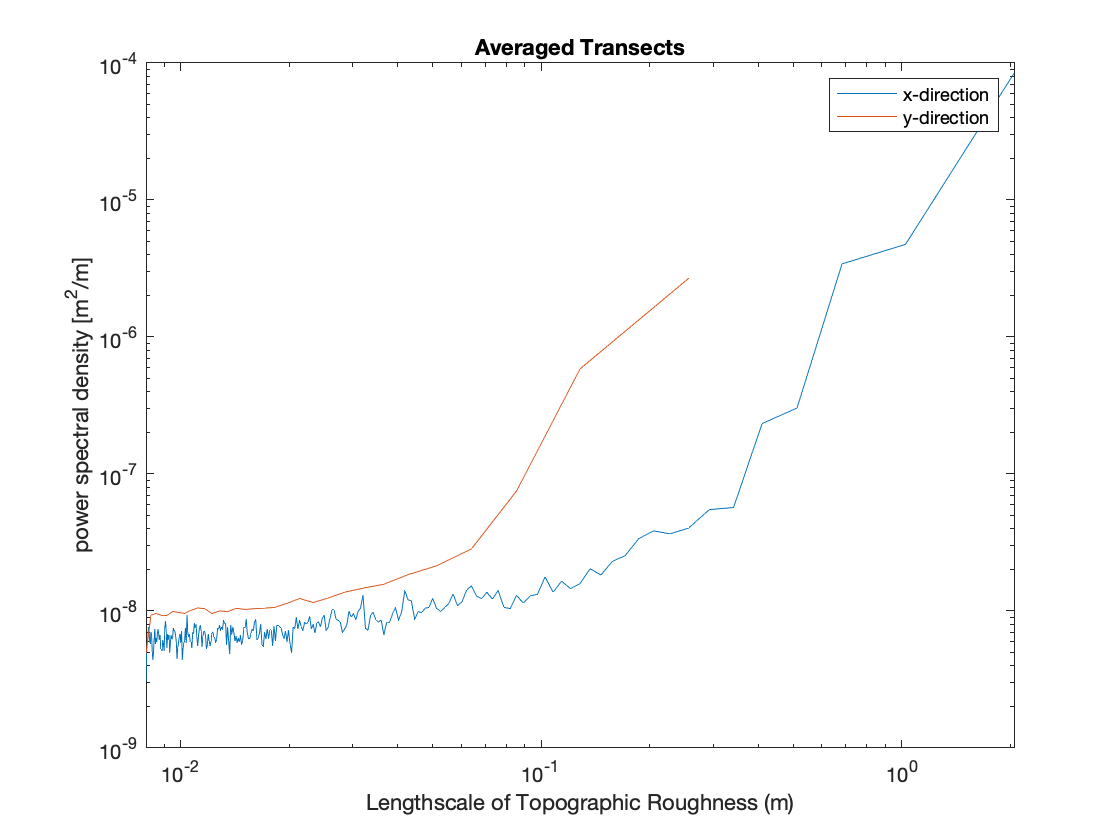

%Calculate periodograms of all columns in z
[Px,fx] = periodogram(detrend(z'),windowx,nfftx,fs,'psd'); %transpose z to make the columns represent the x-direction
[Py,fy] = periodogram(detrend(z),windowy,nffty,fs,'psd');

Pyavg = mean(Py,2);
Pxavg = mean(Px,2);

%turn frequency vectors into wavelength (= lengthscale of topographic roughness = 1/freq)
wx=1./fx;
wy=1./fy;

%Plot periodograms on linear axes
figure(3)
clf
loglog(wx,Pxavg,wy,Pyavg)
xlabel('Lengthscale of Topographic Roughness (m)')
ylabel('power spectral density [m^2/m]')
legend('x-direction','y-direction')
title('Averaged Transects')

#### Try re-running this section without the "detrend" command in each periodogram. How does this change the average spectra, and why? 

#### In what dimension do the spectra indicate higher surface roughness? What does this tell you about the predominant direction of fault slip?

## Filtering

#### Play with the Gaussian filter sigma and window size values below to see what they produce when you run the section.

sigmag = 20; %gaussian filter sigma value (in pixel units)
windowsize = 20; %gaussian filter window size (in pixels)

Now we will plot the filter, surface, and low- and high-pass filtered surfaces.

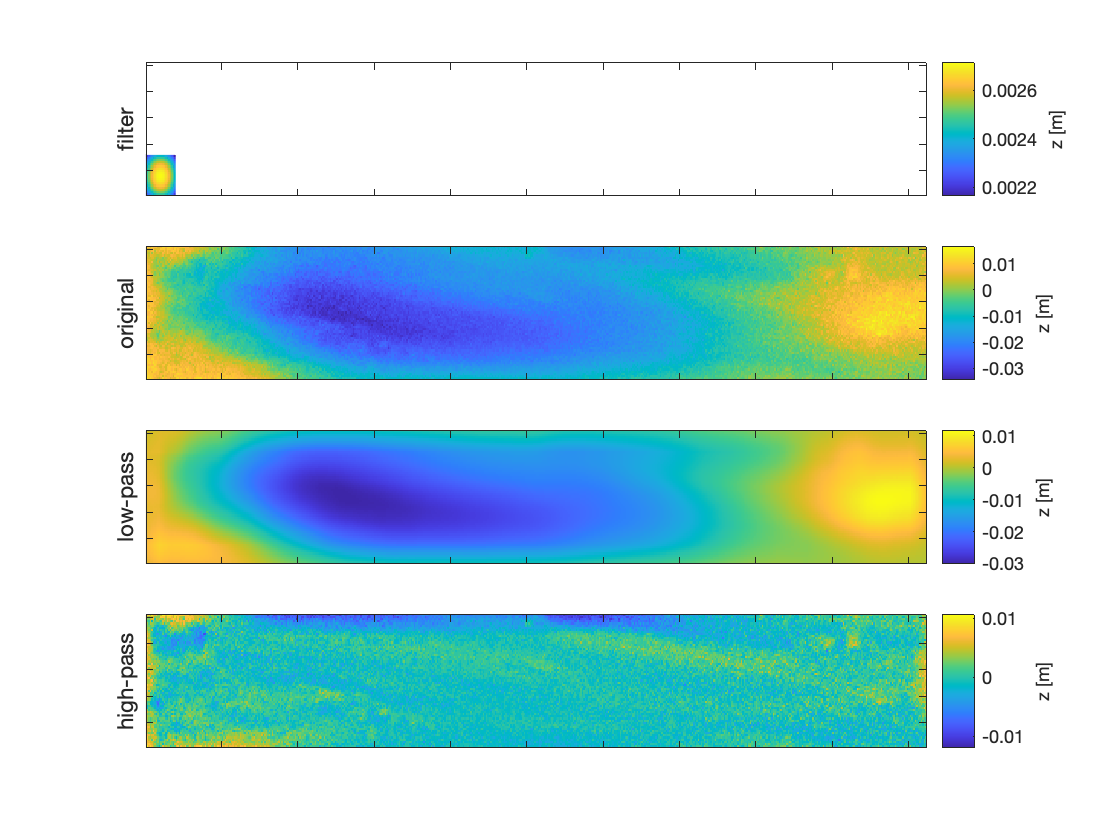

filter = fspecial('gaussian',windowsize,sigmag); %create gaussian filter

[z_lp] = imfilter(z,filter,'conv'); %use filter to produce low pass surface
z_hp = z-z_lp; %generate high pass surface

figure(4)
clf
% Plot the filter, scaled relative to the size of the raster itself
s(1) = subplot(4,1,1);
imagesc(x(1:windowsize),y(1:windowsize),filter)
shading interp
axis xy;
set(gca,'XTickLabel',[],'YTickLabel',[],'xlim',[x(1) x(end)],'ylim',[y(1) y(end)]);
c(1) = colorbar;
ylabel('filter')

%Plot the original, unfiltered raster surface
s(2) = subplot(4,1,2);
imagesc(x,y,z);
axis xy;
set(gca,'XTickLabel',[],'YTickLabel',[],'xlim',[x(1) x(end)],'ylim',[y(1) y(end)]);
c(2) = colorbar;
ylabel('original')

%Plot the low-pass raster surface
s(3) = subplot(4,1,3);
imagesc(x,y,z_lp);
axis xy;
set(gca,'XTickLabel',[],'YTickLabel',[],'xlim',[x(1) x(end)],'ylim',[y(1) y(end)]);
c(3) = colorbar;
ylabel('low-pass')

%Plot the high-pass raster surface
s(4) = subplot(4,1,4);
imagesc(x,y,z_hp);
axis xy;
set(gca,'XTickLabel',[],'YTickLabel',[],'xlim',[x(1) x(end)],'ylim',[y(1) y(end)]);
c(4) = colorbar;
ylabel('high-pass')

%Add colorbar axis labels to all subplots and label without exponent notation
for i=1:4
    c(i).Ruler.Exponent = 0;
    set(get(c(i),'label'),'string','z [m]','Rotation',90);
end




%Calculate periodograms of all columns in z
[Px_hp,fx] = periodogram(z_hp',windowx,nfftx,fs,'psd'); %transpose z to make the columns represent the x-direction
[Py_hp,fy] = periodogram(z_hp,windowy,nffty,fs,'psd');
[Px_lp,fx] = periodogram(z_lp',windowx,nfftx,fs,'psd'); %transpose z to make the columns represent the x-direction
[Py_lp,fy] = periodogram(z_lp,windowy,nffty,fs,'psd');

Py_hpavg = mean(Py_hp,2);
Px_hpavg = mean(Px_hp,2);
Py_lpavg = mean(Py_lp,2);
Px_lpavg = mean(Px_lp,2);


%turn frequency vectors into wavelength (= lengthscale of topographic roughness = 1/freq)
wx = 1./fx;
wy = 1./fy;


%Find the range of PSD values to plot PSDs on the same y-axis
ylims = [min([Px_lpavg;Py_lpavg;Px_hpavg;Py_hpavg]) max([Px_lpavg;Py_lpavg;Px_hpavg;Py_hpavg])];


%Plot periodograms on matching linear axes
figure(5)
clf
subplot(2,1,1)
loglog(wx,Px_lpavg,wy,Py_lpavg)
ylim(ylims);
title('low-pass')
ylabel('PSD')
legend('x-direction','y-direction','location','southeast')

subplot(2,1,2)
loglog(wx,Px_hpavg,wy,Py_hpavg)
ylim(ylims);
title('high-pass')
xlabel('Lengthscale of Topographic Roughness (m)')
ylabel('PSD')

#### What is the difference between the high-pass and low-pass surfaces, and how are those differences represented by their spectra? 

#### Does filtering give you any additional insights into the characteristic differences between roughness in the x- and y- directions? 

#### Can you see any additional applications of this kind of filtering in answering specific questions regarding roughness or identifying specific features?